# Phys 434 Lab 3

## Natalie Shen

### Collaborators: Francesca Bennet, Taylor Prewitt

#### Hours:

clear all; close all; clc

### Problem 1

#### A)

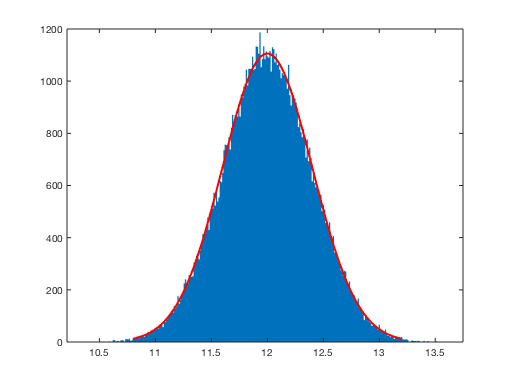

% bt = b.';
% a = transpose((11.6 + (12.4-11.6).*rand(100000,1)));
% A = [a b];
% 
% %subplot(1,1,1);
% histogram(A,200);
% title("Basic Histogram")
% xlabel("Temperature (K)")
% ylabel("Counts")
% 
% %subplot(1,1,2);
% histogram(A,200,"BinLimits",[11.75 12.4]);
% 
% %subplot(1,1,3);
% histfit(A,200)
% xlim([11.2 12.8]);

r = normrnd(12,.4,[1,100000]);
histfit(r);

bd = [10., 10.3, 2.1, 0, 0, 15.6, 22.3, 12.7]

bd =    10.0000   10.3000    2.1000         0         0   15.6000   22.3000   12.7000


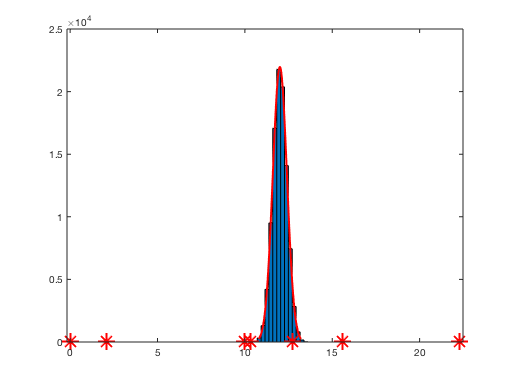

b = [10., 10.3, 2.1, 0, 15.6, 22.3, 12.7];
bq = [1,1,1,2,1,1,1];
A = [r b];
histfit(A,100);
hold on
plot(b, bq, 'r*', 'LineWidth', 2, 'MarkerSize', 15);
hold off

#### B)

Statistical Question:

Which data points stand outside of the normal standard deviation of 0.4?

Will the removal of said data points influence the data as a whole?

Would attempting to filter out the bad data points also result in the removal of the good data points?

#### C)

I'm going to convert all the data points to percentages based on the distribution. I will then be comparing the probabilities to see whether they are within a specific range. If so then this data is then "kept", if not then it is discarded. I will be running thorugh both the normal data and the "bad data".

#### D)

%first run, limit: sigma1
%limits
mu = 12;
sigma = .4;
ll = mu - sigma;
hl = mu + sigma;

%for regular data
g1count = 0;
b1count = 0;
for z = 1:1:length(r)
    if r(z) < ll
        b1count = b1count + 1;
    elseif r(z) > hl
        b1count = b1count + 1;
    else
        g1count = g1count + 1;
    end
end

%for bad data
bg1count = 0;
bb1count = 0;
for z = 1:1:length(bd)
    if bd(z) < ll
        bb1count = bb1count + 1;
    elseif bd(z) > hl
        bb1count = bb1count + 1;
    else
        bg1count = bg1count + 1;
    end
end


%second run, limit: sigma3
%limits
mu = 12;
sigma = .4;
ll = mu - 3 * sigma;
hl = mu + 3 * sigma;

%for regular data
g2count = 0;
b2count = 0;
for z = 1:1:length(r)
    if r(z) < ll
        b2count = b2count + 1;
    elseif r(z) > hl
        b2count = b2count + 1;
    else
        g2count = g2count + 1;
    end
end

%for bad data
bg2count = 0;
bb2count = 0;
for z = 1:1:length(bd)
    if bd(z) < ll
        bb2count = bb2count + 1;
    elseif bd(z) > hl
        bb2count = bb2count + 1;
    else
        bg2count = bg2count + 1;
    end
end

%third run, limit: sigma5
%limits
mu = 12;
sigma = .4;
ll = mu - 5 * sigma;
hl = mu + 5 * sigma;

%for regular data
g3count = 0;
b3count = 0;
for z = 1:1:length(r)
    if r(z) < ll
        b3count = b3count + 1;
    elseif r(z) > hl
        b3count = b3count + 1;
    else
        g3count = g3count + 1;
    end
end

%for bad data
bg3count = 0;
bb3count = 0;
for z = 1:1:length(bd)
    if bd(z) < ll
        bb3count = bb3count + 1;
    elseif bd(z) > hl
        bb3count = bb3count + 1;
    else
        bg3count = bg3count + 1;
    end
end

disp("First run results: (Sigma1)")

First run results: (Sigma1)


g1count

g1count = 68450

b1count

b1count = 31550

bg1count

bg1count = 0

bb1count

bb1count = 8


disp("Second run results: (Sigma3)")

Second run results: (Sigma3)


g2count

g2count = 99747

b2count

b2count = 253

bg2count

bg2count = 1

bb2count

bb2count = 7


disp("Third run results: (Sigma5)")

Third run results: (Sigma5)


g3count

g3count = 100000

b3count

b3count = 0

bg3count

bg3count = 3

bb3count

bb3count = 5

Truth Table:

### B)

The good data that was tossed out decreased more as I increased sigma, which is predictible since earlier sigmas leave out about about 30-40% of data, which is accurate with the findings.

### C)

There will always be mistakes that could occur resulting in bad data being mixed in with the good data. Some are avoidable if you narrow down the limits of where the data is expected to be, in this case narrowing down to anywhere between 3 to 5 ish sigma.

## Problem 2

### 1.

Since the distance traveled is so small that it lies in sigma5 territory, how much distancance (in arcseconds) has the object traveled within that small amount of distance.

distance =  sqrt(x^2 + y^2);

#### 2.

xlim=-3:0.1:3;
X=normpdf(xlim,0,1);
Y=normpdf(xlim,0,1);
D=(X.^2+Y.^2).^.5;
r=raylpdf(D,2)

r =     0.0016    0.0021    0.0028    0.0037    0.0048    0.0062    0.0079    0.0100    0.0125    0.0155    0.0191    0.0232    0.0279    0.0332    0.0391    0.0456    0.0526    0.0601    0.0680    0.0761    0.0843    0.0924    0.1003    0.1077    0.1146    0.1207    0.1259    0.1300    0.1331    0.1349    0.1355    0.1349    0.1331    0.1300    0.1259    0.1207    0.1146    0.1077    0.1003    0.0924    0.0843    0.0761    0.0680    0.0601    0.0526    0.0456    0.0391    0.0332    0.0279    0.0232


%prob of sigma 5 is 1 out of 3.5 million
sigma5p=1/(3.5 * 10.^6);
five_sig_valR=icdf("rayleigh", 1-sigma5p,1,2)

five_sig_valR = 5.4897

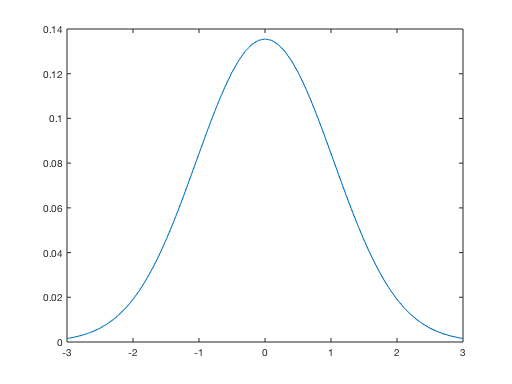

plot(xlim,r);

Timestamp: 3 hrs tuesday, 4 ish hours saturday